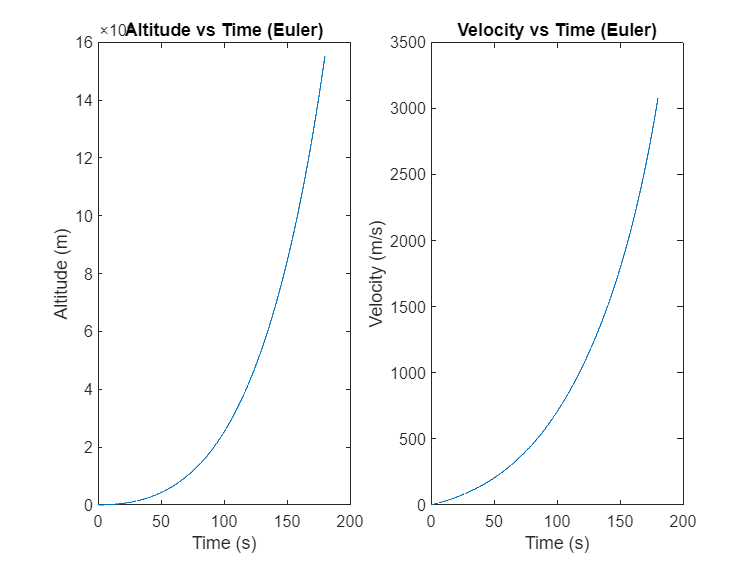

ROCKET; %import rocket geo

t0 = 0;
tf = 180;
dt = 0.01;

g=9.81;

time = t0:dt:tf;

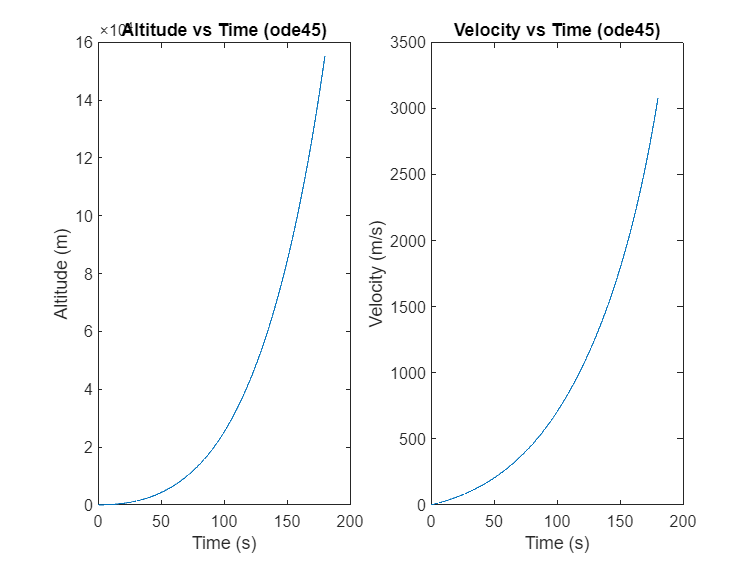

[T, S] = ode45(@(t,s) eom(t,s,g,m0,mdot,Ae,Pe,ve,Cd,refA), time, [y0, v0]);

figure

subplot(1,2,1)
plot(T,S(:,1))
title("Altitude vs Time (ode45)")
xlabel("Time (s)")
ylabel("Altitude (m)")
subplot(1,2,2)
plot(T,S(:,2))
title("Velocity vs Time (ode45)")
xlabel("Time (s)")
ylabel("Velocity (m/s)")

S(end,1)

ans = 1.5531e+05

maxes = [0, 0, 0];
for i=1:length(S)
    v = S(i,2);
    h = S(i,1);
    [T_, a, P, rho] = atmosisa(h, extended=true, action="none");
    Fd = Drag(Cd, refA, rho, v);
    if Fd > maxes(1)
        maxes(1) = Fd;
        maxes(2) = v / a;
        maxes(3) = h;
    end
end
sprintf("Max drag force: %d N, mach at point: %.3d, altitude at point: %d m", maxes)

ans = "Max drag force: 1.633281e+05 N, mach at point: 1.311e+00, altitude at point: 1.098506e+04 m"

function sdot = eom(t,s,g,m0,mdot,Ae,Pe,ve,Cd,refA)
    h = s(1);    
    v = s(2);
    [T_, a_, P, rho] = atmosisa(h, extended=true, action="none");
    m = m0 - mdot*t;
    Ft = Thrust(mdot, ve, Ae, Pe, P);
    Fd = Drag(Cd, refA, rho, v);
    sdot(1,1) = v;
    sdot(2,1) = (Ft - Fd)/m - g;
end

function Ft=Thrust(mdot, ve, Ae, Pe, P)
    Ft = mdot*ve + Ae*(Pe - P);
end

function Fd=Drag(Cd, refA, rho, v)
    Fd = .5 * Cd * refA * rho * v^2;
end